% Reset
close all;
clear all;

%%%%%%%%%%               User configurations               %%%%%%%%%%
axesColor = 'Black';
% Set default plot limits
xlimCfg = [-1.5, 1.5];
ylimCfg = [-1.5, 1.5];
zlimCfg = [-1.5, 1.5];
% Set axes labels
xlab = 'i';
ylab = 'j';
zlab = 'k';
aspect = [1, 1, 1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Ejercicio 1.5 Vecindades unitarias en diferentes normas

Recuerde el concepto de círculo unitario de la ecuación (1.10) para la norma 2. Considere los conjuntos de puntos a una distancia **unitaria** del origen utilizando las normas 1, 2 y 3 en el espacio R2.

- ¿Cómo se ven estos conjuntos geométricamente?

- Repita el ejercicio usando ahora los vectores en R3.

- ¿Puede dar una descripción de cómo se verían estos conjuntos en espacios de mayores dimensiones?

### Para $\Re^2$

#### Con la norma $p=1$

Definición de norma:


$$\parallel v\parallel_p ={\left(v_1^p +v_2^p +\cdots +v_n^p \right)}^{\frac{1}{p}}$$


Para   un vector $v$ tal que $v\in \Re^2$ y que ${\parallel v\parallel }_1 =1$ donde:


$$v=\left(i\;,j\right)$$


Sustituyendo $p=1$ y $v$ 


$$\parallel v\parallel_1 =\left|i\right|+\left|j\right|=1$$


Se obtiene la función de la línea  que delimita la longitud de $\parallel v\parallel_1$ en $Q_1$ del plano cartesiano y se despeja para $j$.


$$Q_1 =\left|i\right|+\left|j\right|=1$$



$$j=1-i$$


%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%%
hold on;

% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
xL = xlim;
yL = ylim;
line([0 0], yL,'Color', axesColor);  %y-axis
line(xL, [0 0],'Color', axesColor);  %x-axis
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Acotando [0,1] en pasos de 0.005
i = [0:0.005:1];
% Plot Q1
j = 1 - i;
plot(i, j,'Color', [0 0.4470 0.7410])


La cual, limitada  de [0,1], se obtiene la siguiente  recta.

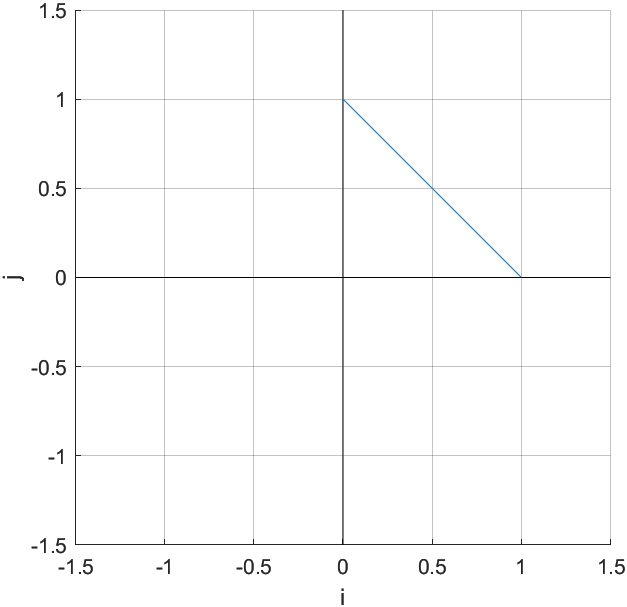

Despejando para $Q_2$, $Q_3$ y $Q_4$


$$Q_2 =-\left|i\right|+\left|j\right|=1$$



$$j=1+i$$



$$Q_3 =-\left|i\right|-\left|j\right|=1$$



$$j=-1-i$$



$$Q_4 =\left|i\right|-\left|j\right|=1$$



$$j=i-1$$


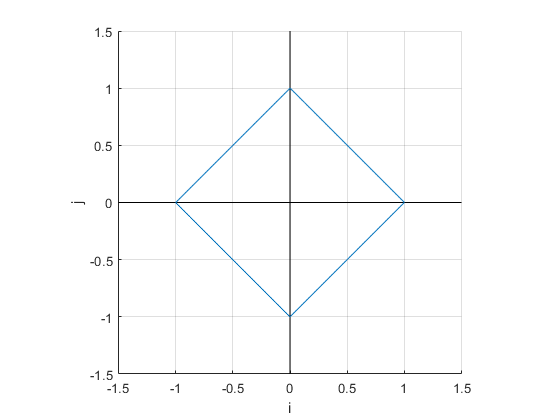

% Plot Q2
i = [0:-0.005:-1];
j = 1 + i;
plot(i, j, 'Color', [0 0.4470 0.7410])
% Plot Q3
j = -1 -i;
plot(i, j, 'Color', [0 0.4470 0.7410])
% Plot Q4
i = [0:0.005:1];
j = i - 1;
plot(i, j, 'Color', [0 0.4470 0.7410])
hold off

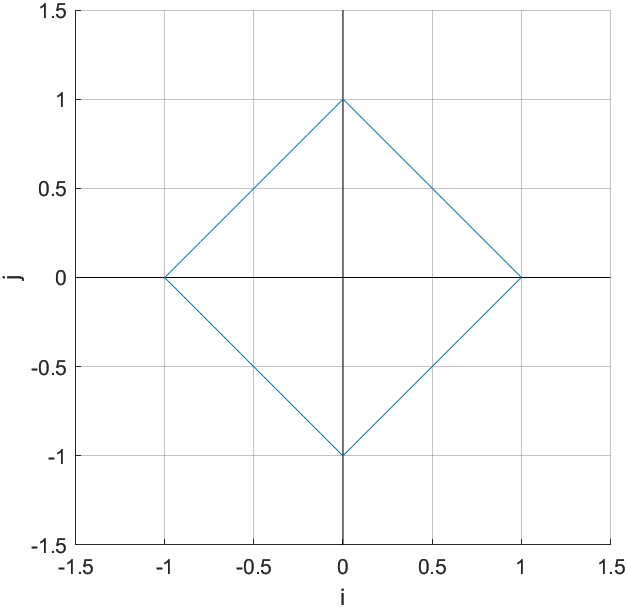

Obteniendo  como resultado, el perímetro de un cuadrado rotado 45°. Es decir, cualquier punto que caiga en el perímetro generado, pertenecerá a la norma 1 en $\Re^2$.

### Con la norma $p=2$

Sustituyendo en ecuación **NORMA** $p=2$ y $v$

$\parallel v\parallel_2 ={\left(i^2 +j^2 \right)}^{\frac{1}{2}}$ = 1

Se obtiene la fórmula del círculo  que delimita la longitud de $\parallel v\parallel_2$ en $Q_1$y en $Q_2$ del plano cartesiano y se despeja para $j$.


$$j=\left|\sqrt{1-i^2 }\right|$$


Debido a que se considera $Q_1$y $Q_2$, se pueden graficar ambos cuadrantes delimitando de [-1,1].

i = [-1:0.005:1];
% Plot Q1 and Q2
j = sqrt(1-i.^2);
plot(i, j, 'Color', [0 0.4470 0.7410]);
hold on;

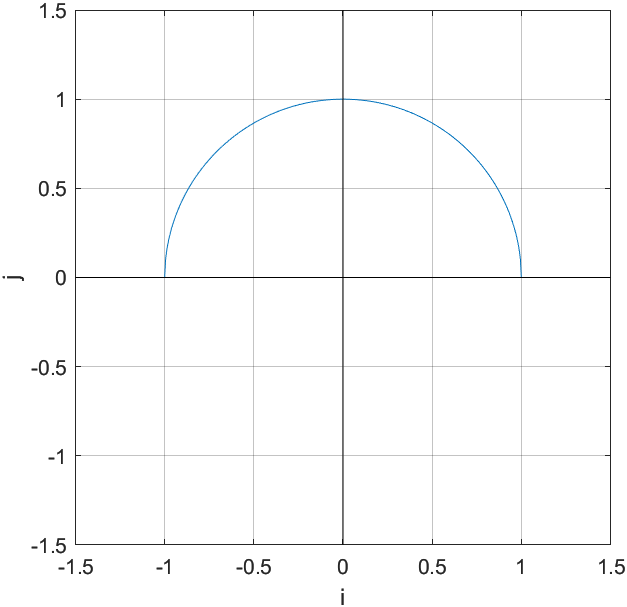

La parte inferior del círculo, estará dada por la fórmula:


$$j=-\left|\sqrt{1-i^2 }\right|$$


Donde también se podrá graficar $Q_3$y $Q_4$ al mismo tiempo:

i = [-1:0.005:1];
% Plot Q3 and Q4
j = -sqrt(1-i.^2);
plot(i, j, 'Color', [0 0.4470 0.7410]);


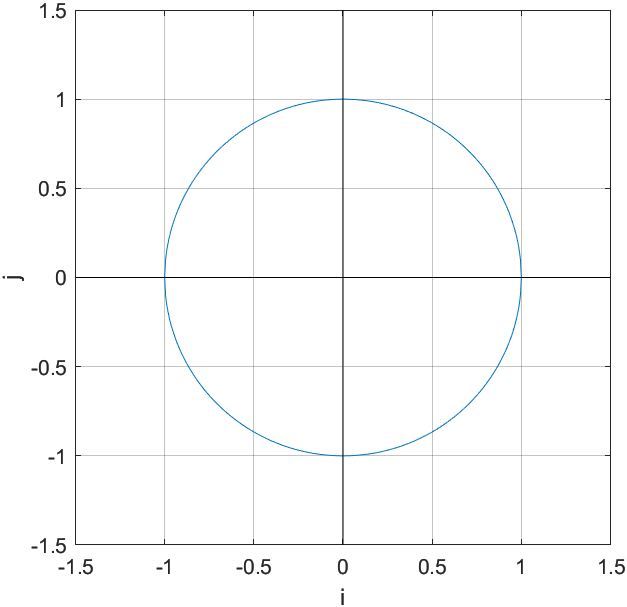

Obteniendo  como resultado, el perímetro de un círculo con $r=1$. Es decir, cualquier punto que caiga en el perímetro generado, pertenecerá a la norma 2 en $\Re^2$.

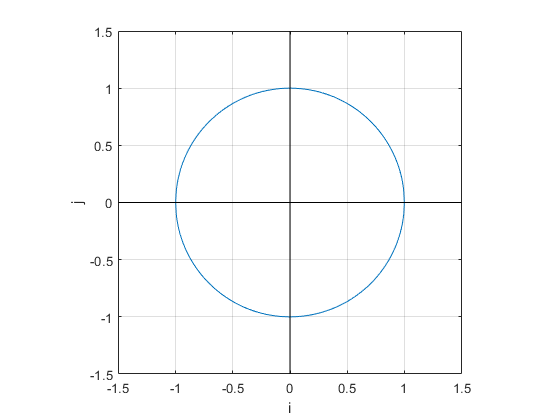

%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
xL = xlim;
yL = ylim;
line([0 0], yL,'Color', axesColor);  %y-axis
line(xL, [0 0],'Color', axesColor);  %x-axis
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Con la norma $p=3$

Sustituyendo en ecuación **NORMA** $p=3$ y $v$


$$\parallel v\parallel_3 ={\left(i^3 +j^3 \right)}^{\frac{1}{3}} =1$$


Se obtiene la siguiente fórmula que delimita la longitud de $\parallel v\parallel_3$ en $Q_1$ del plano cartesiano y se despeja para $j$.


$$Q_1 ={\left(i^3 +j^3 \right)}^{\frac{1}{3}} =1$$



$$j={\left(1-i^3 \right)}^{\frac{1}{3}}$$


i = [0:0.005:1];
% Plot Q1
j = (1 - i.^3).^(1/3);
plot(i, j, 'Color', [0 0.4470 0.7410])
hold on

La cual, limitada  de [0,1], se obtiene la siguiente  recta.

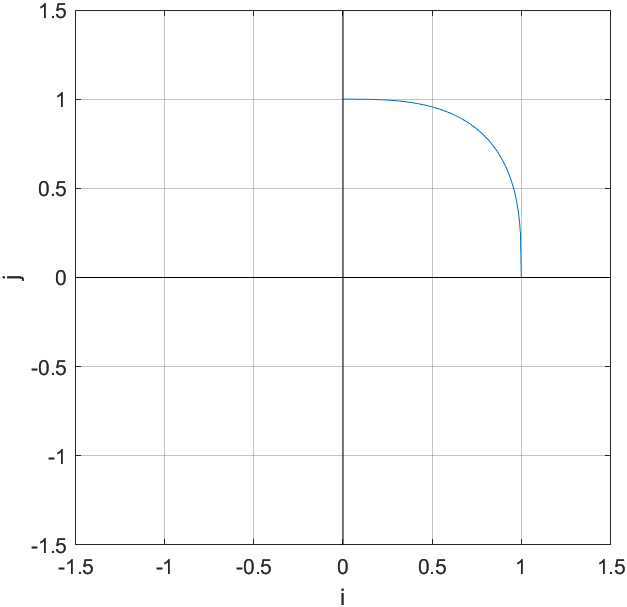

Despejando para $Q_2$:


$$Q_2 ={\left({-i}^3 +j^3 \right)}^{\frac{1}{3}} =1$$



$$j={\left(1+i^3 \right)}^{\frac{1}{3}}$$


Para obtener los valores de $Q_3$ y $Q_4$:


$$Q_3 =Q_2 \;\left(-1\right)$$



$$j={-\left(1+i^3 \right)}^{\frac{1}{3}}$$



$$Q_4 =Q_1 \left(-1\right)$$



$$j={-\left(1-i^3 \right)}^{\frac{1}{3}}$$


% Plot Q2
i = [0:-0.005:-1];
j = (1 + i.^3).^(1/3);
plot(i, j, 'Color', [0 0.4470 0.7410])
% Plot Q3
j = -(1 + i.^3).^(1/3);
plot(i, j, 'Color', [0 0.4470 0.7410])
% Plot Q4
i = [0:0.005:1];
j = -(1 - i.^3).^(1/3);
plot(i, j, 'Color', [0 0.4470 0.7410])


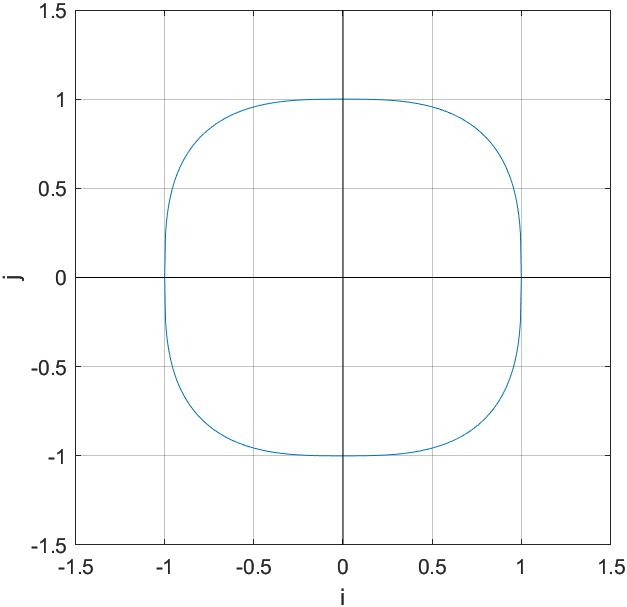

Obteniendo  como resultado, el perímetro de un cuadrado con las esquinas redondeadas. Es decir, cualquier punto que caiga en el perímetro generado, pertenecerá a la norma 3 en $\Re^2$.

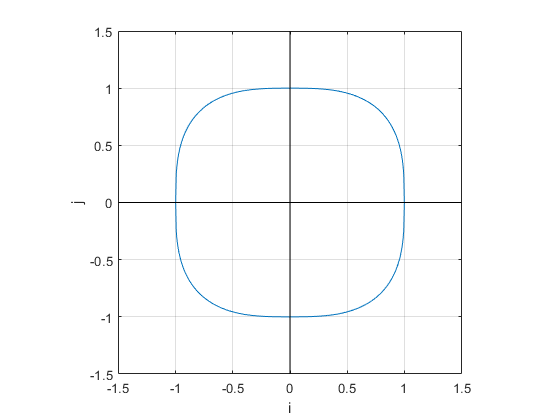

%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
xL = xlim;
yL = ylim;
line([0 0], yL,'Color', axesColor);  %y-axis
line(xL, [0 0],'Color', axesColor);  %x-axis
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Para $\Re^3$

#### Con la norma $p=1$

Definición de norma:


$$\parallel v\parallel_p ={\left(v_1^p +v_2^p +\cdots +v_n^p \right)}^{\frac{1}{p}}$$


Para   un vector $v$ tal que $v\in \Re^3$ y que ${\parallel v\parallel }_1 =1$ donde:


$$v=\left(i\;,\;j,\;k\right)$$


Sustituyendo $p=1$ y $v$ 


$$\parallel v\parallel_1 =\left|i\right|+\left|j\right|\;+\;\left|k\right|=1$$


Se obtiene la función de la línea  que delimita la longitud de $\parallel v\parallel_1$ en $Q_1$ del plano cartesiano y se despeja para $j$.


$$Q_1 =\left|i\right|+\left|j\right|+\left|k\right|=1$$



$$j=1-i-k$$


Para facilitar el proceso de visualización en $\Re^3$, se graficará un plano a la vez. Para poder graficar el plano $\textrm{ij}$, se asume que $k=0$. Por lo que en el plano $\textrm{ij}$:


$$Q_1 =$$

$$j=1-i$$



$$Q_2 =$$

$$j=1+i$$



$$Q_3 =$$

$$j=-1-i$$



$$Q_4 =$$

$$j=i-1$$


%% For ij plane (k = 0)
i = [0:0.005:1];
j = [0:0.005:1];
k = zeros(size(i));

% Q1
j = 1 - i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);
hold on

% Q2
i = [0:-0.005:-1];
j = 1 + i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q3
j = -1 - i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

%Q4
i = [0:0.005:1];
j = -1 + i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);


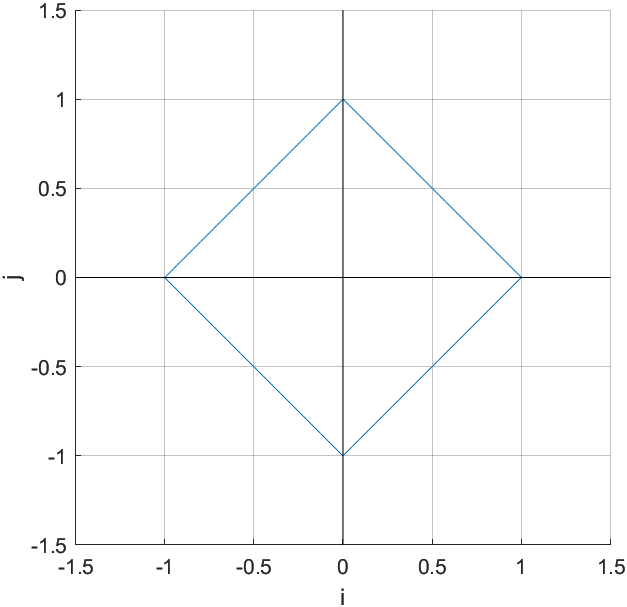

Para el plano $\textrm{ik},j=0$ y para $\textrm{kj},i=0$. Por lo tanto:

**Plano **$\textrm{ik}$


$$Q_1 =$$

$$k=1-i$$



$$Q_2 =$$

$$k=1+i$$



$$Q_3 =$$

$$k=-1-i$$



$$Q_4 =$$

$$k=i-1$$


**Plano **$\textrm{kj}$


$$Q_1 =$$

$$k=1-j$$



$$Q_2 =$$

$$k=1+j$$



$$Q_3 =$$

$$k=-1-j$$



$$Q_4 =$$

$$k=i-j$$


%% For ik plane
i = [0:0.005:1];
j = zeros(size(i));
k = i ;

% Q1
k = 1 - i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q2
i = [0:-0.005:-1];
k = 1 + i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q3
k = -1 - i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q4
i = [0:0.005:1];
k = -1 + i;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

%% For kj
i = zeros(size(j));
j = [0:0.005:1];
k = i ;

% Q1
k = 1 - j;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q2
j = [0:-0.005:-1];
k = 1 + j;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q3
k = -1 - j;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q4
j = [0:0.005:1];
k = -1 + j;
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

Obteniendo las aristas de la siguiente figura en $\Re^3$:

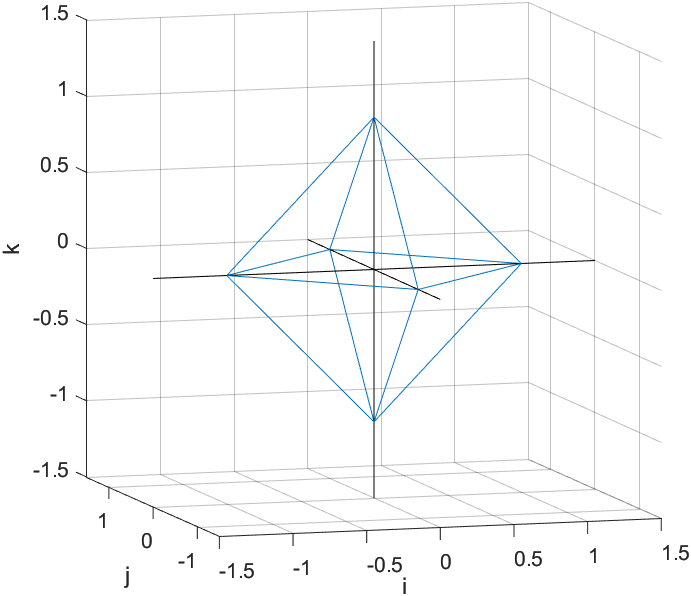

En ${\parallel v\parallel }_1$ en $\Re^2$, cualquier punto que cayera en el perímetro satisfacía la norma. En este caso, siguen siendo las mismas figuras, pero ahora tienen profundidad. Debido a esto, cualquier punto que se encuentre en el área de las caras delimitadas por las aristas, pertenecerá a la norma ${\parallel v\parallel }_2$ en $\Re^3$. Es importante aclarar que cualquier punto dentro de la figura no pertenece a la norma.

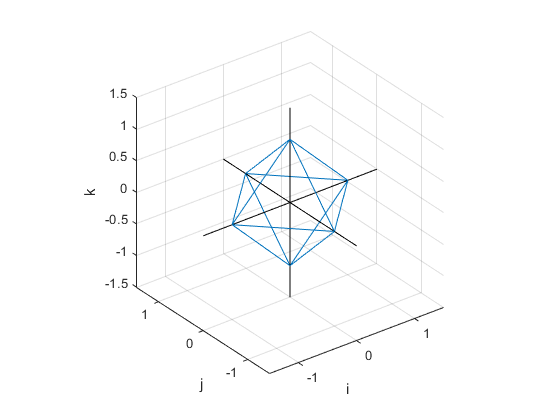


%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
zlim(zlimCfg);
xL = xlim;
yL = ylim;
zL = zlim;
line(xL, [0 0],'Color', axesColor);             % x
line([0 0], yL,'Color', axesColor);             % y
line([0 0], [0 0], zL, 'Color', axesColor);     % z
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### Con la norma $p=2$

Definición de norma:


$$\parallel v\parallel_p ={\left(v_1^p +v_2^p +\cdots +v_n^p \right)}^{\frac{1}{p}}$$


Para   un vector $v$ tal que $v\in \Re^3$ y que ${\parallel v\parallel }_2 =1$ donde:


$$v=\left(i\;,\;j,\;k\right)$$


Sustituyendo $p=2$ y $v$ 

$\parallel v\parallel_2 ={\left(i^2 +j^2 +k^2 \right)}^{\frac{1}{2}}$ = 1

Para facilitar el proceso de visualización en $\Re^3$, se graficará un plano a la vez. Para poder graficar el plano $\textrm{ij}$, se asume que $k=0$. Sustituyendo se obtiene la función de la línea  que delimita la longitud de $\parallel v\parallel_2$ en $Q_1$y $Q_2$ del plano cartesiano y se despeja para $j$.


$$Q_{1,2} =\left|i\right|+\left|j\right|+\left|k\right|=1$$



$$j=\left|\sqrt{1-i^2 -k^2 }\right|$$



$$j=\left|\sqrt{1-i^2 }\right|$$



$$Q_{3,4} =j=-\left|\sqrt{1-i^2 }\right|$$


i = [-1:0.005:1];
j = [-1:0.005:1];
k = zeros(size(i));
%% For ij plane

% Q1 and Q2
j = sqrt(1-i.^2);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);
hold on

% Q3 and Q4
j = -sqrt(1-i.^2);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

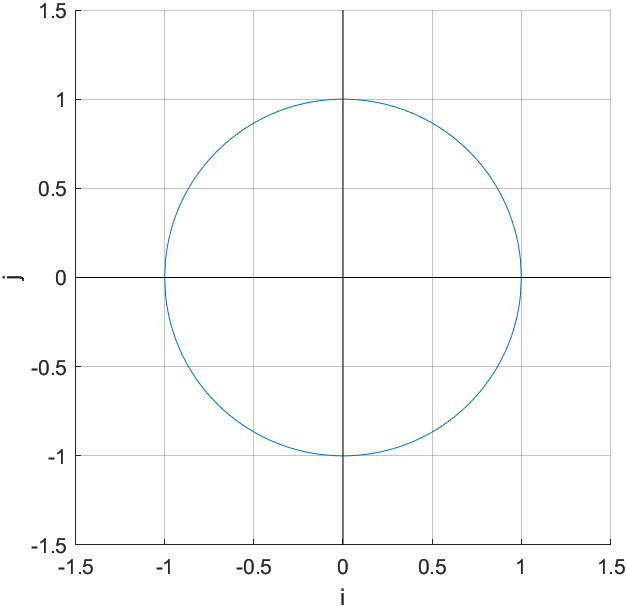

Para el plano $\textrm{ik},j=0$ y para $\textrm{kj},i=0$. Por lo tanto:

**Plano **$\textrm{ik}$


$$Q_{1,2} =k=\left|\sqrt{1-i^2 }\right|$$



$$Q_{3,4} =k=-\left|\sqrt{1-i^2 }\right|$$


**Plano **$\textrm{kj}$


$$Q_{1,2} =k=\left|\sqrt{1-j^2 }\right|$$



$$Q_{3,4} =k=-\left|\sqrt{1-j^2 }\right|$$


%% For ik plane
i = [-1:0.005:1];
j = zeros(size(i));
k = i ;

% Q1 and Q2
k = sqrt(1-i.^2);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);
hold on

% Q3 and Q4
k = -sqrt(1-i.^2);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

%% For kj plane
i = zeros(size(j));
j = [-1:0.005:1];
k = i ;

% Q1 and Q2
k = sqrt(1-j.^2);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);
hold on

% Q3 and Q4
k = -sqrt(1-j.^2);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

Obteniendo las aristas de la siguiente figura en $\Re^3$:

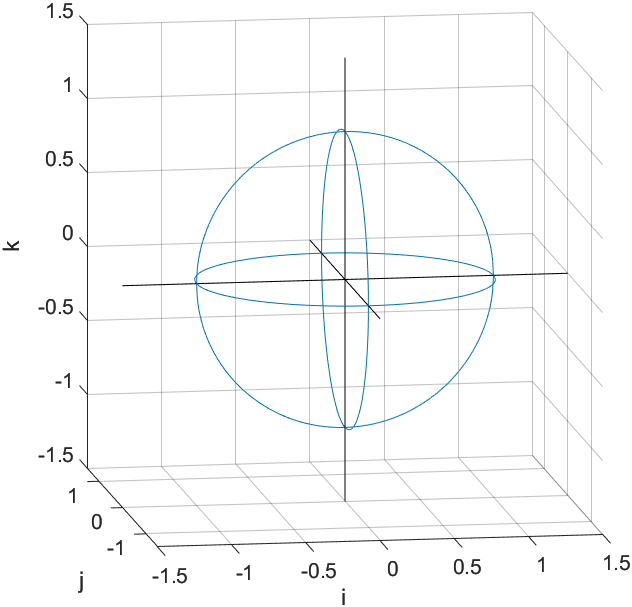

En ${\parallel v\parallel }_2$ en $\Re^2$, cualquier punto que cayera en el perímetro satisfacía la norma. En este caso, siguen siendo las mismas figuras, pero ahora tienen profundidad. Debido a esto, cualquier punto que se encuentre en la superficie de la esfera limitada por las aristas, pertenecerá a la norma ${\parallel v\parallel }_2$ en $\Re^3$. Es importante aclarar que cualquier punto dentro de la figura no pertenece a la norma.

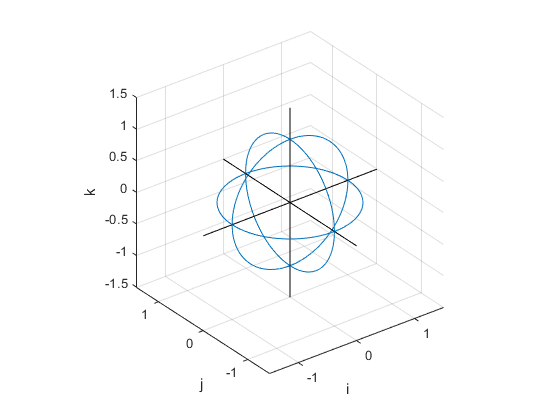

%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
zlim(zlimCfg);
xL = xlim;
yL = ylim;
zL = zlim;
line(xL, [0 0],'Color', axesColor);             % x
line([0 0], yL,'Color', axesColor);             % y
line([0 0], [0 0], zL, 'Color', axesColor);     % z
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### Con la norma $p=3$

Definición de norma:


$$\parallel v\parallel_p ={\left(v_1^p +v_2^p +\cdots +v_n^p \right)}^{\frac{1}{p}}$$


Para   un vector $v$ tal que $v\in \Re^3$ y que ${\parallel v\parallel }_3 =1$ donde:


$$v=\left(i\;,\;j,\;k\right)$$


Sustituyendo $p=3$ y $v$ 

$\parallel v\parallel_3 ={\left(i^3 +j^3 +k^3 \right)}^{\frac{1}{3}}$ = 1

Para facilitar el proceso de visualización en $\Re^3$, se graficará un plano a la vez. Para poder graficar el plano $\textrm{ij}$, se asume que $k=0$. Sustituyendo se obtiene la función de la línea  que delimita la longitud de $\parallel v\parallel_3$ en $Q_1$ del plano cartesiano y se despeja para $j$.


$$Q_1 ={\left(i^3 +j^3 \right)}^{\frac{1}{3}} =1$$



$$j={\left(1-i^3 \right)}^{\frac{1}{3}}$$


Para $Q_2 ,Q_3 \;y\;Q_4$


$$Q_2 ={\left({-i}^3 +j^3 \right)}^{\frac{1}{3}} =1$$



$$j={\left(1+i^3 \right)}^{\frac{1}{3}}$$



$$Q_3 =Q_2 \;\left(-1\right)$$



$$j={-\left(1+i^3 \right)}^{\frac{1}{3}}$$



$$Q_4 =Q_1 \left(-1\right)$$



$$j={-\left(1-i^3 \right)}^{\frac{1}{3}}$$


i = [0:0.005:1];
j = [0:0.005:1];
k = zeros(size(i));

%% For ij plane

% Q1
j = (1 - i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);
hold on

% Q2
i = [0:-0.005:-1];
j = (1 + i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q3
j = -(1 + i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q4
i = [0:0.005:1];
j = -(1 - i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

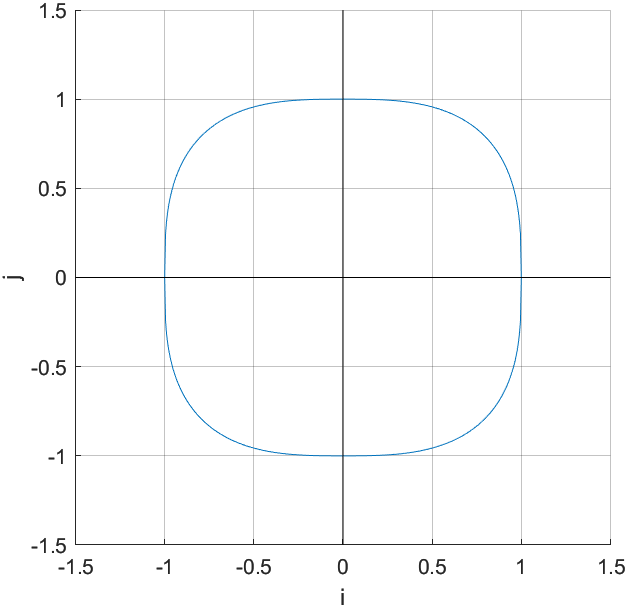

Para el plano $\textrm{ik},j=0$ y para $\textrm{kj},i=0$. Por lo tanto:

**Plano **$\textrm{ik}$


$$Q_1 =k={\left(1-i^3 \right)}^{\frac{1}{3}}$$



$$Q_2 =$$
 
$$k={\left(1+i^3 \right)}^{\frac{1}{3}}$$



$$Q_3 =k=-{\left(1+i^3 \right)}^{\frac{1}{3}}$$



$$Q_4 =$$

$$k={-\left(1-i^3 \right)}^{\frac{1}{3}}$$


**Plano **$\textrm{kj}$


$$Q_1 =k={\left(1-j^3 \right)}^{\frac{1}{3}}$$



$$Q_2 =$$
 
$$k={\left(1+j^3 \right)}^{\frac{1}{3}}$$



$$Q_3 =k=-{\left(1+j^3 \right)}^{\frac{1}{3}}$$



$$Q_4 =$$

$$k={-\left(1-j^3 \right)}^{\frac{1}{3}}$$


%% For ik plane
i = [0:0.005:1];
j = zeros(size(i));
k = [0:0.005:1];

% Q1
k = (1 - i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q2
i = [0:-0.005:-1];
k = (1 + i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q3
k = -(1 + i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q4
i = [0:0.005:1];
k = -(1 - i.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

%% For kj plane
i = zeros(size(i));
j = [0:0.005:1];
k = [0:0.005:1];

% Q1
k = (1 - j.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q2
j = [0:-0.005:-1];
k = (1 + j.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q3
k = -(1 + j.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

% Q4
j = [0:0.005:1];
k = -(1 - j.^3).^(1/3);
plot3(i, j, k, 'Color', [0 0.4470 0.7410]);

Obteniendo las aristas de la siguiente figura en $\Re^3$:

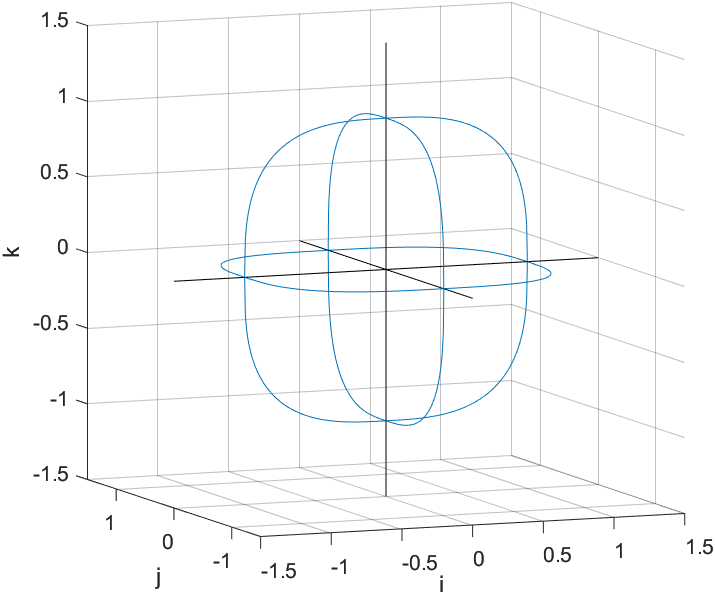

En ${\parallel v\parallel }_3$ en $\Re^2$, cualquier punto que cayera en el perímetro satisfacía la norma. En este caso, siguen siendo las mismas figuras, pero ahora tienen profundidad. Debido a esto, cualquier punto que se encuentre en la superficie de las caras limitada por las aristas, pertenecerá a la norma ${\parallel v\parallel }_3$ en $\Re^3$. Es importante aclarar que cualquier punto dentro de la figura no pertenece a la norma.

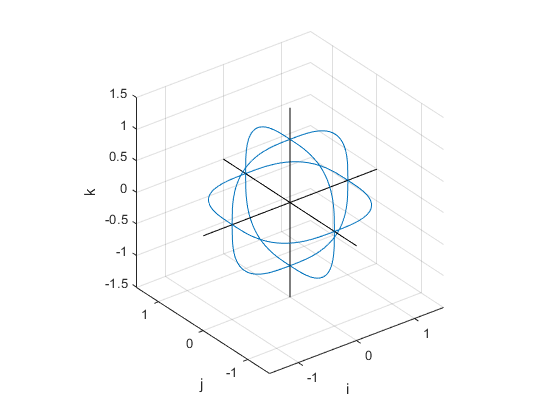


%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
zlim(zlimCfg);
xL = xlim;
yL = ylim;
zL = zlim;
line(xL, [0 0],'Color', axesColor);             % x
line([0 0], yL,'Color', axesColor);             % y
line([0 0], [0 0], zL, 'Color', axesColor);     % z
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Para espacios $>\Re^3$

En $\Re^2$ los puntos que satisfacían la norma, tenían coordenadas $i,j$.Sin embargo solo son puntos, es decir 1 dimensión. En $\Re^3$, las mismas coordenadas ahora tienen profundidad si se ve cualquiera de los 3 planos de forma perpendicular. Sin embargo, al visualizar las caras formadas por las aristas de forma perpendicular, los puntos  tienen coordenadas $i,j$ (alto y ancho). Si está tendencia continúa para $>\Re^3$, se podrá concluir que  en un espacio $\Re^n$ donde $n>3\;$se tendran $n-1$ dimensiones. Por ejemplo, en $\Re^4$ las normas tendrán alto, ancho y profundidad.